% read audio files 
[y_audio1, Fs_audio1] = audioread('audio_in_noise1.wav');
[y_audio2, Fs_audio2] = audioread('audio_in_noise2.wav');
[y_audio3, Fs_audio3] = audioread('audio_in_noise3.wav');

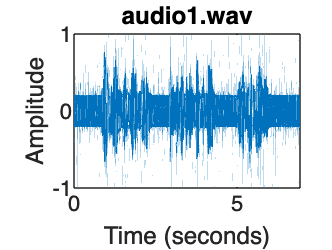

% plot signal against time 
% audio1.wav
y_audio1 = y_audio1(:,1); % ensures that it is a single channel recording 
N_audio1 = length(y_audio1); % finds length 
t_audio1 = (0:N_audio1-1)/Fs_audio1; % calculate time vector 

figure;
plot(t_audio1, y_audio1);
title('audio1.wav');
xlabel('Time (seconds)');
ylabel('Amplitude');
saveas(gcf, 'timeplot_audio1.png')

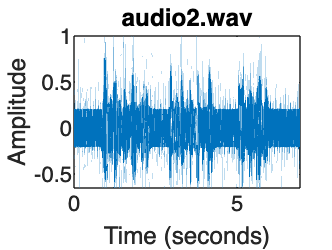


% audio2.wav
y_audio2 = y_audio2(:,1); 
N_audio2 = length(y_audio2);
t_audio2 = (0:N_audio2-1)/Fs_audio2; 

figure;
plot(t_audio2, y_audio2);
title('audio2.wav');
xlabel('Time (seconds)');
ylabel('Amplitude');
saveas(gcf, 'timeplot_audio2.png')

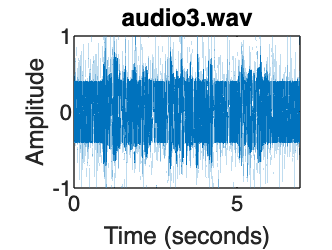


% audio3.wav
y_audio3 = y_audio3(:,1); 
N_audio3 = length(y_audio3);
t_audio3 = (0:N_audio3-1)/Fs_audio3; 

figure;
plot(t_audio3, y_audio3);
title('audio3.wav');
xlabel('Time (seconds)');
ylabel('Amplitude');
saveas(gcf, 'timeplot_audio3.png')

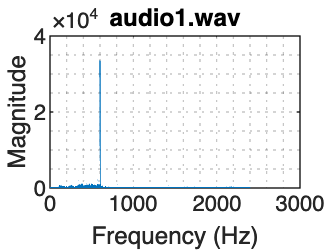

% plotting spectra of files showing frequency content 
% audio1.wav 
fft_audio1 = fft(y_audio1);
f_audio1 = linspace(0, Fs_audio1/20, length(fft_audio1)/20+1);% Only plot the first half due to symmetry. This frequency is chosen due to nyquist frequency 
plot(f_audio1, abs(fft_audio1(1:length(f_audio1))));
title('audio1.wav');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid minor 
saveas(gcf, 'frequencyplot_audio1.png')

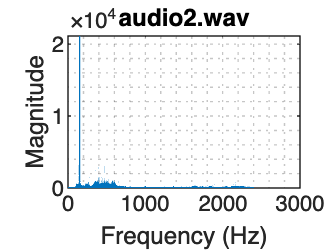


% audio2.wav
fft_audio2 = fft(y_audio2);
f_audio2 = linspace(0, Fs_audio2/20, length(fft_audio2)/20+1);% Only plot the first half due to symmetry. This frequency is chosen due to nyquist frequency 
plot(f_audio2, abs(fft_audio2(1:length(f_audio2))));
title('audio2.wav');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid minor
saveas(gcf, 'frequencyplot_audio2.png')

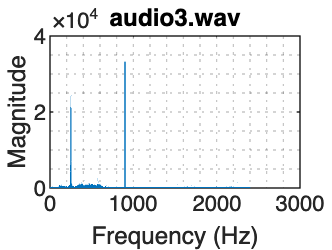


% audio3.wav
fft_audio3 = fft(y_audio3);
f_audio3 = linspace(0, Fs_audio3/20, length(fft_audio3)/20+1);% Only plot the first half due to symmetry. This frequency is chosen due to nyquist frequency 
plot(f_audio3, abs(fft_audio3(1:length(f_audio3))));
title('audio3.wav');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid minor
saveas(gcf, 'frequencyplot_audio3.png')

audio1 - 600 Hz  

audio 2 - 150 Hz  

audio 3 - 250 Hz, 900Hz 

Found the frequency of the background noise by using fast fourier transform to plot frequency spectra of each audio recording. Compared graphs and identified similar patterns between them (this must be base signal). Identified differneces between graphs (this must be background noise) 

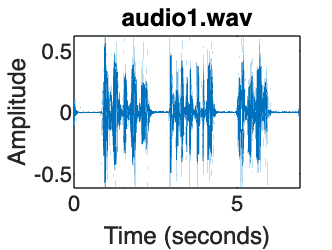

% filter audio1.wav
%d = designfilt('bandstopiir', 'FilterOrder', 2, 'HalfPowerFrequency1', 575, 'HalfPowerFrequency2', 625, 'DesignMethod', 'butter', 'SampleRate', Fs_audio1);
d = designfilt('bandstopiir', 'FilterOrder', 2, 'HalfPowerFrequency1', 595, 'HalfPowerFrequency2', 605, 'DesignMethod', 'butter', 'SampleRate', Fs_audio1);
%fvtool(d, 'Fs', Fs_audio1);
result = filtfilt(d, y_audio1);

% plot frequency and time graph 
% time 
plot(t_audio1, result)
title('audio1.wav');
xlabel('Time (seconds)');
ylabel('Amplitude');
saveas(gcf, 'noiseremoved_timeplot_audio1.png')

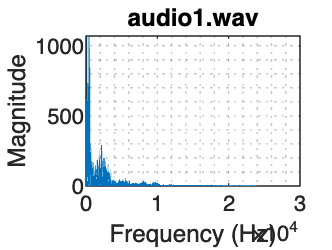



% frequency 
fft_audio1 = fft(result);
f_audio1 = linspace(0, Fs_audio1/2, length(fft_audio1)/2+1);% Only plot the first half due to symmetry. This frequency is chosen due to nyquist frequency 
plot(f_audio1, abs(fft_audio1(1:length(f_audio1))));
title('audio1.wav');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid minor 
saveas(gcf, 'noiseremoved_frequencyplot_audio1.png')


% save frequency filtered audio 
audiowrite('noise_removed_audio1.wav', result, Fs_audio1)

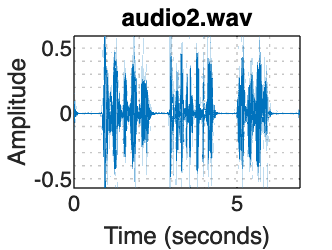

% filter audio2.wav
%d = designfilt('bandstopiir', 'FilterOrder', 2, 'HalfPowerFrequency1', 575, 'HalfPowerFrequency2', 625, 'DesignMethod', 'butter', 'SampleRate', Fs_audio1);
d = designfilt('bandstopiir', 'FilterOrder', 2, 'HalfPowerFrequency1', 145, ...
    'HalfPowerFrequency2', 155, 'DesignMethod', 'butter', 'SampleRate', Fs_audio2);
%fvtool(d, 'Fs', Fs_audio1);
result = filtfilt(d, y_audio2);

% plot frequency and time graph 
% time 
plot(t_audio2, result)
title('audio2.wav');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid minor 
saveas(gcf, 'noiseremoved_timeplot_audio2.png')

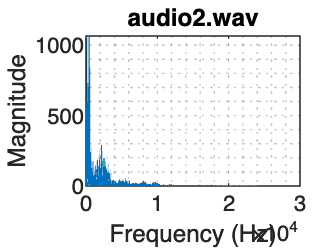


% frequency 
fft_audio2 = fft(result);
f_audio2 = linspace(0, Fs_audio2/2, length(fft_audio2)/2+1);% Only plot the first half due to symmetry. This frequency is chosen due to nyquist frequency 
plot(f_audio2, abs(fft_audio2(1:length(f_audio2))));
title('audio2.wav');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid minor 
saveas(gcf, 'noiseremoved_frequencyplot_audio2.png')


% save frequency filtered audio 
audiowrite('noise_removed_audio2.wav', result, Fs_audio2)

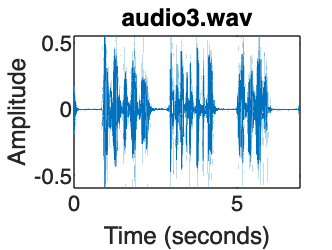

% filter audio3.wav
filter1 = designfilt('bandstopiir', 'FilterOrder', 2, 'HalfPowerFrequency1', 895, 'HalfPowerFrequency2', 905, 'DesignMethod', 'butter', 'SampleRate', Fs_audio3);
result1 = filtfilt(filter1, y_audio3);
filter2 = designfilt('bandstopiir', 'FilterOrder', 2, 'HalfPowerFrequency1', 245, 'HalfPowerFrequency2', 255, 'DesignMethod', 'butter', 'SampleRate', Fs_audio3);
result2 = filtfilt(filter2, result1);

% plot frequency and time graph 
% time 
plot(t_audio3, result2)
title('audio3.wav');
xlabel('Time (seconds)');
ylabel('Amplitude');
saveas(gcf, 'noiseremoved_timeplot_audio3.png')

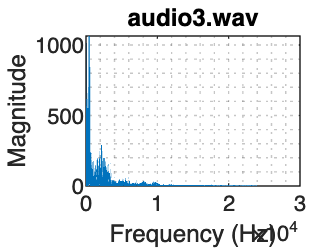


% frequency 
fft_audio3 = fft(result2);
f_audio3 = linspace(0, Fs_audio3/2, length(fft_audio3)/2+1);% Only plot the first half due to symmetry. This frequency is chosen due to nyquist frequency 
plot(f_audio3, abs(fft_audio3(1:length(f_audio3))));
title('audio3.wav');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid minor 
saveas(gcf, 'noiseremoved_frequencyplot_audio3.png')


% save frequency filtered audio 
audiowrite('noise_removed_audio3.wav', result2, Fs_audio2)